% Citation for this code and algorithm:
% Fienup, James R.
% "Reconstruction of an object from the modulus of its Fourier transform.",
% Optics letters 3.1 (1978): 27-29.
%%%%%%%%%%%%%%%%%%%%%

clear all
clf

% import data
FourierAmplitudeConstraint = h5read('CDI_exercise.h5','/data/FourierAmplitudeConstraint');
RealSpaceSupport = h5read('CDI_exercise.h5','/data/RealSpaceSupport');
InitialGuesReal = h5read('CDI_exercise.h5','/data/InitialGuesReal');
InitialGuessImaginary = h5read('CDI_exercise.h5','/data/InitialGuessImaginary');

% parameter setting
beta = 0.7;
iteration = 5;
i_HIO = 45;
i_ER = 5;

% initial guess
gx = InitialGuesReal + i*InitialGuessImaginary;
Fx = FourierAmplitudeConstraint;
%imagesc(real(gx))
%colormap gray;
%colorbar;
EF = zeros(1,iteration);
% iteration
for ii_iteration = 1: iteration
    fprintf('Iteration: %d\n', ii_iteration) 
    
    % Hybrid-Input-Output algorithm
    for ii_HIO = 1: i_HIO
        
        % step 1: calculate the Fourier transform of gx
        Gx = fftshift(fft2(gx));
        
        % step 2: update guess
        Gx_update = real(Fx).*exp(i*angle(Gx));
        
        % step 3: inverse Fourier transform
        gx_update = ifft2(ifftshift(Gx_update));
        
        % step 4: define g1 -- HIO
        for m = 1 : 256
            for n = 1: 256
                if ((gx_update(m,n) > 0) && (RealSpaceSupport(m,n) > 0))
                    gx1(m,n) = gx_update(m,n);
                else
                    gx1(m,n) = gx(m,n) - beta*gx_update(m,n);        
                end
            end
        end        
        gx = gx1;
        
    end
    
    for ii_ER = 1: i_ER
        
        % step 1: calculate the Fourier transform of gx
        Gx = fftshift(fft2(gx));
        
        % step 2: update guess
        Gx_update = real(Fx).*exp(i*angle(Gx));
        
        % step 3: inverse Fourier transform
        gx_update = ifft2(ifftshift(Gx_update));
        
        % step 4: define g1 -- ER
        for m = 1 : 256
            for n = 1: 256
                if ((gx_update(m,n) > 0) && (RealSpaceSupport(m,n) > 0))
                    gx1(m,n) = gx_update(m,n);
                else
                    gx1(m,n) = 0;        
                end
            end
        end        
        gx = gx1;
    end
a = (abs(Gx)-abs(Fx)).^2;
b = abs(Fx).^2;
EF(ii_iteration) = sqrt(sum(a(:))/sum(b(:)));
end

Iteration: 1
Iteration: 2
Iteration: 3
Iteration: 4
Iteration: 5


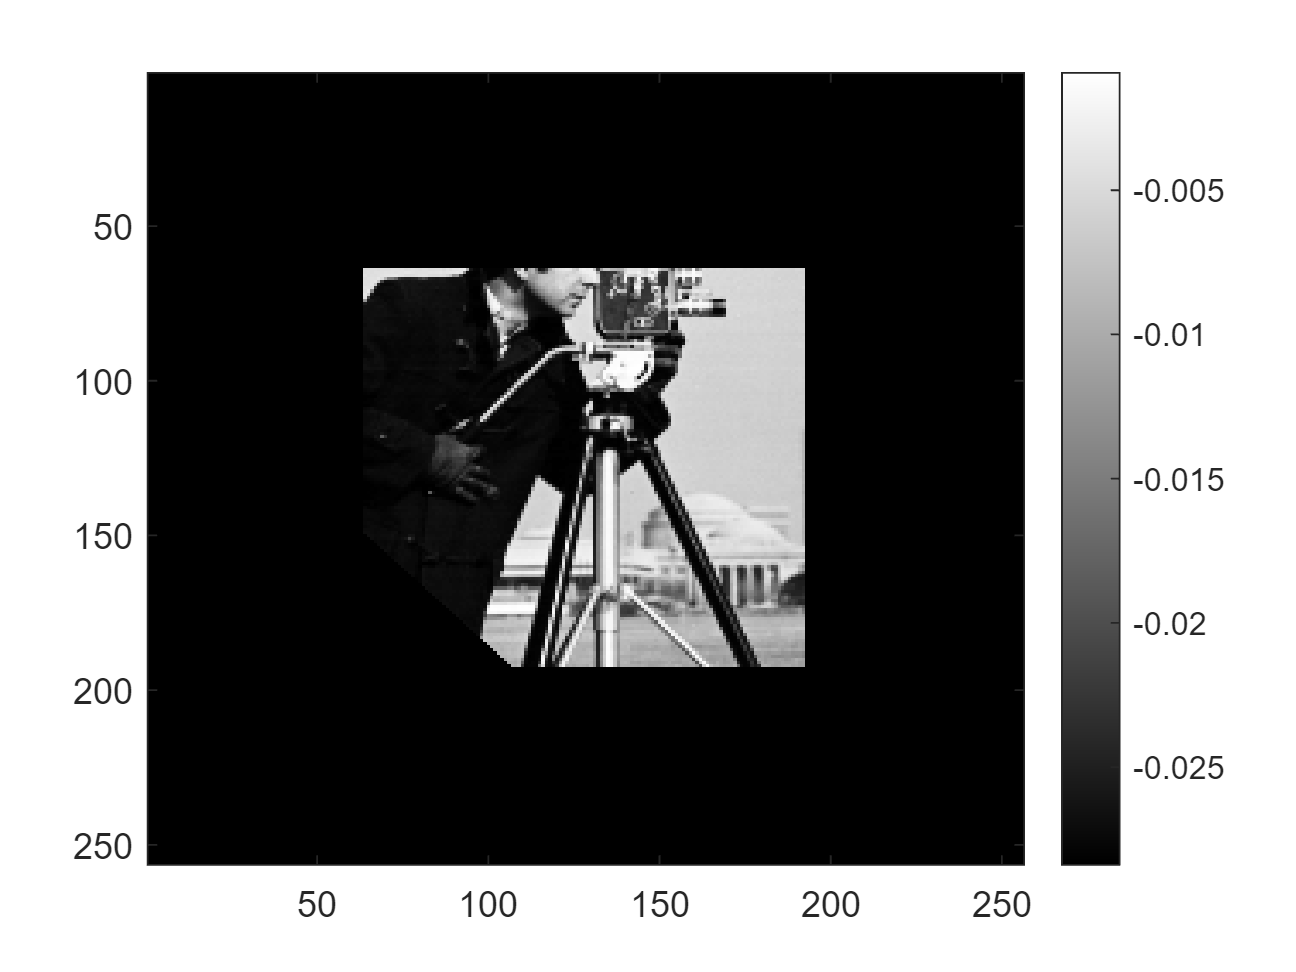

% show the image
imagesc(log(real(gx)))
colorbar;
colormap gray;

%title('reconstructed image')

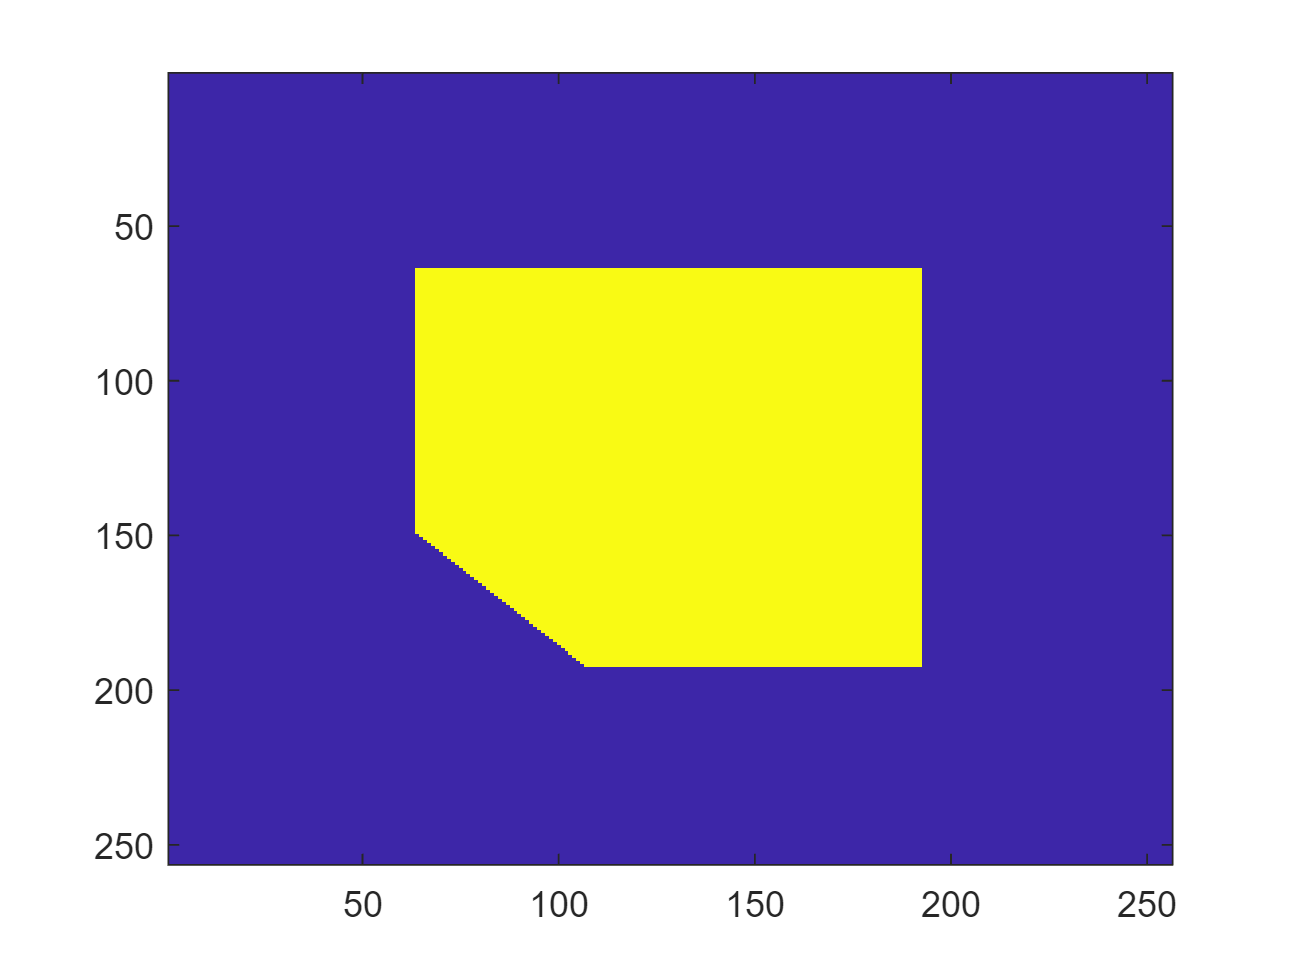

figure()
imagesc(RealSpaceSupport)

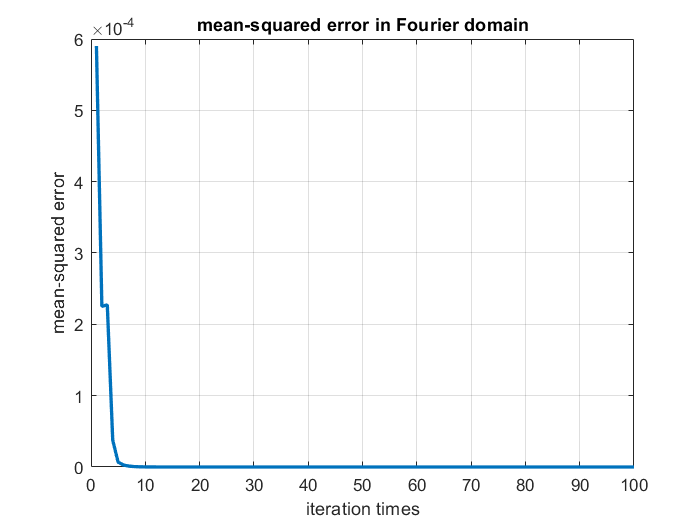

% plot trend of mean-squared error
x = 1:iteration;
plot(x,EF,'LineWidth',2)
grid on
title("mean-squared error in Fourier domain")
xlabel("iteration times")
ylabel("mean-squared error")

%ylim([min(EF) max(EF)])